# Neural network based adaptive control of nonlinear uncertain systems

## *Input saturation constraint*

clear; clc;

## Simulation initialization

**Time interval initialization:**

Ts = 0.05;
t = 0:Ts:100;

**Define the desired trajector using a *****smooth function*****:**

xd = [sin(0.5*t) + cos(0.25*t); 0.5*cos(0.5*t) - 0.25*sin(0.25*t)];

**Model related initialization:**

x0 = [0.5; 0.5];
zeta0 = [0; 0]; % auxliar system states initialization
mu = 0.1;

**Input control signal constraint bounds:**

input_upperbound = 2;
input_lowerbound = -2;

**Neural network parameters:**

input_size = 4; % number of inputs
hidden_layer_size = 20; % number of hidden neurons

**Neural network hyperparameters:**

Ac = -eye(2); 
K = -eye(2);
h = -[10; 10];
lr = 2; % learining rate
gamma = 0.0001; % damping factor

**Neural network weights initialization:**

Vc = rands(hidden_layer_size, input_size);
Wc = rands(1, hidden_layer_size);

**Simulation initialization:**

x = zeros(2, length(t));
x(:, 1) = x0;
zeta = zeros(2, length(t));
zeta(:, 1) = zeta0;

u = zeros(length(t), 1);
e = zeros(2, length(t));
delta_u = 0;

changeMoment = ceil(length(t)/2);

## Numeric Simulation

for i = 1:length(t) - 1
    if i == changeMoment
        mu = mu + 2;
    end
    
    % compute current tracking error
    e(:, i) = x(:, i) - xd(:, i) - zeta(:, i);
    
    % neural network input
    x_cnn = [e(:, i); xd(:, i)];
    
    if delta_u >= input_upperbound
        delta_u = 1;
    else
        if delta_u <= input_lowerbound
            delta_u = 1;
        else
            delta_u = 0;
        end
    end
    
    % backpropagation
    dWc = e(:, i)'*(-inv(Ac)*ones(2, 1) + inv(K)*h*delta_u)*(-tanh(Vc*x_cnn))';
    dVc = (e(:, i)'*(-inv(Ac)*ones(2, 1) + inv(K)*h*delta_u)*(-Wc*diag(1 - tanh(Vc*x_cnn).^2)))'*x_cnn';
    
    Wc = Wc + Ts*(-lr*dWc - gamma*norm(e(:, i))*Wc - gamma*norm(zeta(:, i))*Wc);
    Vc = Vc + Ts*(-lr*dVc - gamma*norm(e(:, i))*Vc - gamma*norm(zeta(:, i))*Vc);
    
    % inference
    u(i) = -Wc*tanh(Vc*x_cnn);
    
    % saturation effect applied on the control signal
    [u(i), delta_u] = control_saturation(u(i), input_lowerbound, input_upperbound);
    
    x(:, i + 1) = x(:, i) + Ts*van_der_pol_derivative(x(:, i), u(i), mu) + normrnd(0, 0.009, [2, 1]);
    zeta(:, i + 1) = zeta(:, i) + Ts*aux_system_derivative(zeta(:, i), delta_u, K, h);
end

## Results visualization

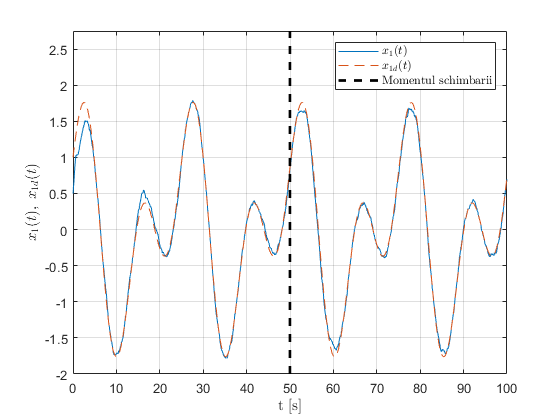

q = -10:Ts:10;
lineWidth = 2;
fontSize = 18;

figure, 
plot(t, x(1, :)); hold on; grid;
plot(t, xd(1, :), "--");
plot(t(changeMoment)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
xlabel("t [s]", "Interpreter","latex");
ylabel("$x_1(t),\;x_{1d}(t)$", "Interpreter","latex");
legend("$x_1(t)$", "$x_{1d}(t)$", "Momentul schimbarii", "Interpreter", "Latex", "Location","northeast");
axis([0 t(end) -2 5.5/2])

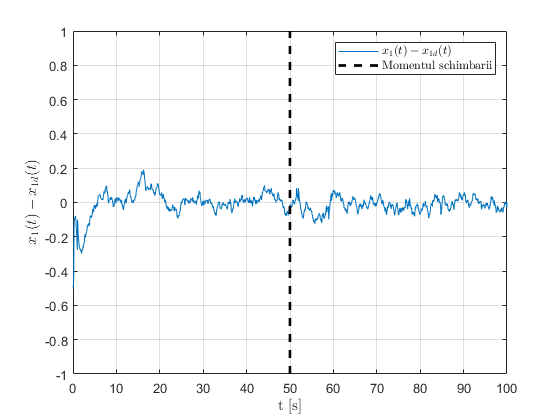


figure, 
plot(t, e(1, :)); grid; hold on;
plot(t(changeMoment)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
xlabel("t [s]", "Interpreter","latex");
ylabel("$x_1(t) - x_{1d}(t)$", "Interpreter","latex");
legend("$x_1(t) - x_{1d}(t)$", "Momentul schimbarii", "Interpreter", "Latex", "Location","northeast");
axis([0 t(end) -1 1])

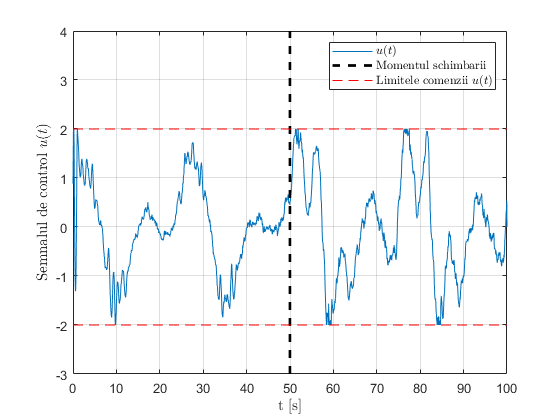


figure,
plot(t, u); grid; hold on;
plot(t(changeMoment)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
plot(t, input_upperbound*ones(size(t)), "Color", "Red", "LineStyle","--");
plot(t, input_lowerbound*ones(size(t)), "Color", "Red", "LineStyle","--");
xlabel("t [s]", "Interpreter","latex");
ylabel("Semnalul de control $u(t)$", "Interpreter","latex");
legend("$u(t)$", "Momentul schimbarii", "Limitele comenzii $u(t)$",  "Interpreter", "Latex", "Location","northeast");
axis([0 t(end) input_lowerbound-1 input_upperbound + 2])

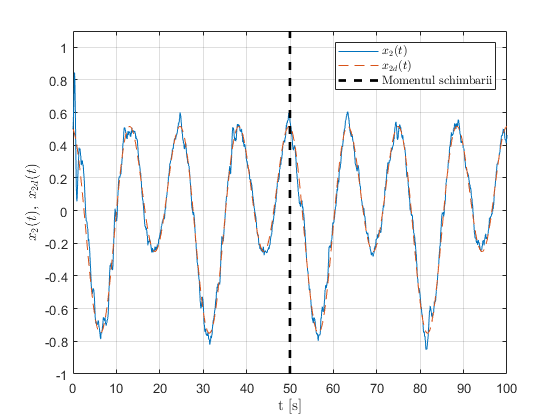


figure, 
plot(t, x(2, :)); hold on; grid;
plot(t, xd(2, :), "--");
plot(t(changeMoment)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
xlabel("t [s]", "Interpreter","latex");
ylabel("$x_2(t),\;x_{2d}(t)$", "Interpreter","latex");
legend("$x_2(t)$", "$x_{2d}(t)$", "Momentul schimbarii", "Interpreter", "Latex", "Location","northeast");
axis([0 t(end) -1 1.1])

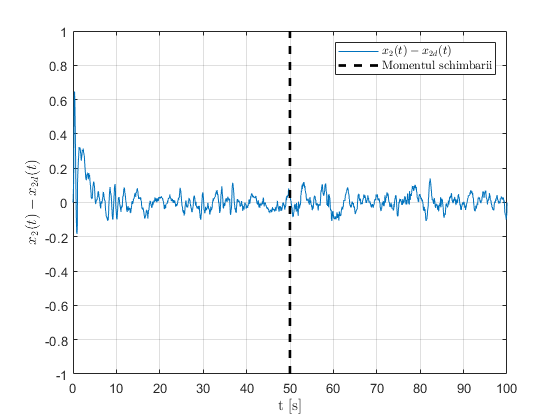


figure, 
plot(t, e(2, :)); grid; hold on;
plot(t(changeMoment)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
xlabel("t [s]", "Interpreter","latex");
ylabel("$x_2(t) - x_{2d}(t)$", "Interpreter","latex");
legend("$x_2(t) - x_{2d}(t)$", "Momentul schimbarii", "Interpreter", "Latex", "Location","northeast");
axis([0 t(end) -1 1])

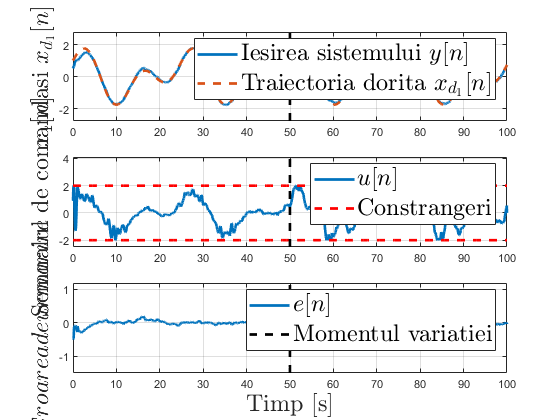


figure,
subplot(3, 1, 1);
plot(t, x(1, :), "LineWidth", lineWidth); hold on; grid;
plot(t, xd(1, :), "--", "LineWidth", lineWidth);
plot(t(changeMoment)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
ylabel("$x_1[n]$ si $x_{d_1}[n]$", "Interpreter","latex", 'FontSize', fontSize);
legend("Iesirea sistemului $y[n]$",  "Traiectoria dorita $x_{d_1}[n]$", "Interpreter", "Latex", "Location","northeast", 'FontSize', fontSize);
axis([0 t(end) min(x(1, :))-1 max(x(1, :))+1])

subplot(3, 1, 2);
plot(t, u, "LineWidth",2); grid; hold on;
plot(t, input_upperbound*ones(size(t)), "Color", "Red", "LineStyle","--", "LineWidth", lineWidth);
plot(t, input_lowerbound*ones(size(t)), "Color", "Red", "LineStyle","--", "LineWidth", lineWidth);
plot(t(changeMoment)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
ylabel("Semnalul de comanda", "Interpreter","latex", 'FontSize', fontSize);
legend("$u[n]$", "Constrangeri", "Interpreter", "Latex", "Location","northeast", 'FontSize', fontSize);
axis([0 t(end) input_lowerbound-0.5 input_upperbound + 2.1])

subplot(3, 1, 3);
plot(t, e(1, :), "LineWidth", lineWidth); grid; hold on;
plot(t(changeMoment)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
xlabel("Timp [s]", "Interpreter","latex", 'FontSize', fontSize);
ylabel("$Eroarea de urmarire$", "Interpreter","latex", 'FontSize', fontSize);
legend("$e[n]$", "Momentul variatiei", "Interpreter", "Latex", "Location","northeast", 'FontSize', fontSize);
axis([0 t(end) min(e(1, :)) - 1 max(e(1, :)) + 1])